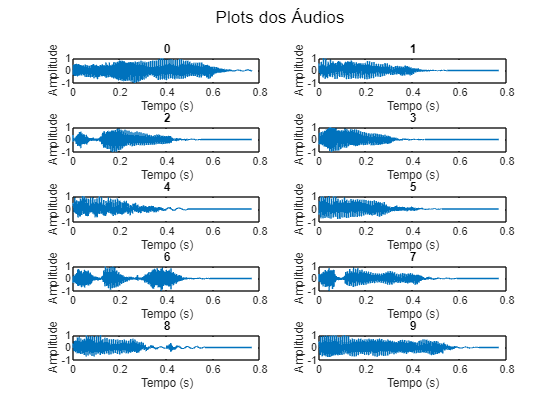

numFich = 10;

dados = ImportarDados(numFich);
dados = RemoverSilencio(dados,numFich);
Graficos(dados);

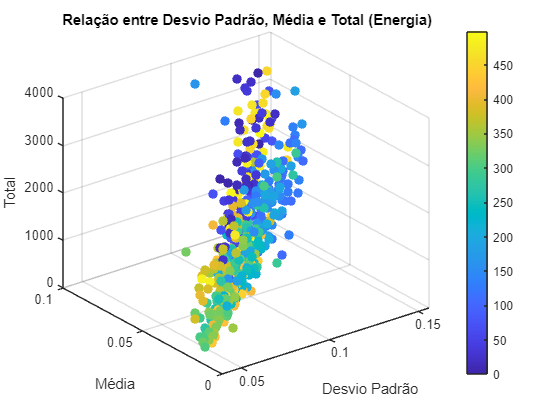


[dadosTotal,numFichTotal] = ImportarTotalDados();

for i = 1:numFichTotal
    energia = dadosTotal{i}.energia;
    desvioPad = std(energia);
    media = mean(energia);
    total = sum(energia);
    dadosTotal{i}.desvio = desvioPad;
    dadosTotal{i}.media = media;
    dadosTotal{i}.total = total;
end

Grafico3D(dadosTotal,numFichTotal);

Foi escolhida a energia total, o desvio padrão da energia e a média da mesma, devido ao facto de ser possivel tirar boas conclusões através da análise da comparação entre as mesmas. Por exemplo, o número 6 apresenta uma média de energia baixa e um desvio padrão baixo logo, conclui-se que os valores não distam muito da média o que origina uma energia total baixa. Pela mesma ordem de pensamento, o número 9 apresenta uma média de energia elevada em comparação com os restantes números mas o seu desvio padrão continua a ser relativamente baixo resultanto numa energia total mais alta do que a dos restantes elementos.

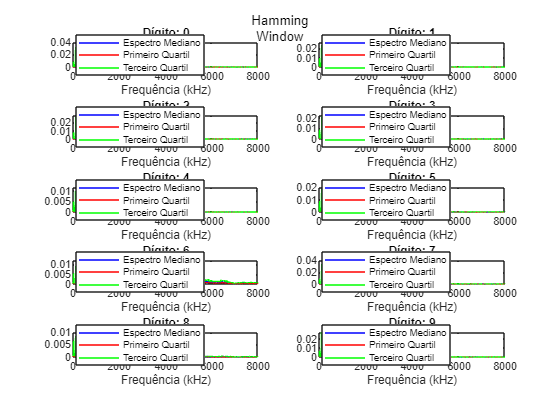


% Meta 2 - Ex 5
% Hamming
num_casos = dadosTotal{1}.dadosFreq / 2;
espectro_mediano = zeros(numFich, num_casos);
primeiro_quartil = zeros(numFich, num_casos);
terceiro_quartil = zeros(numFich, num_casos);

figure;

for i = 1:numFich

    all_spectra = zeros(50, num_casos);
    
    for j = 1:50
        % Obter o áudio e a frequência de amostragem do arquivo atual
        audio = dadosTotal{(i - 1) * 50 + j}.amplitude;
        fs = dadosTotal{(i - 1) * 50 + j}.dadosFreq;

        sinal = [audio; zeros(48000 - length(audio), 1)];
        window = hamming(48000);
        sinal = sinal .* window;

        % Calculo do espectro de amplitude
        S = fft(sinal, num_casos); %transformada de fourier
        all_spectra(j, :) = abs(S) / num_casos;
    end

    % Calcula o espectro de amplitude mediano para cada dígito
    espectro_mediano(i, :) = median(all_spectra, 1);
    
    % Calcula o primeiro quartil para cada dígito
    primeiro_quartil(i, :) = quantile(all_spectra, 0.25);
    
    % Calcula o terceiro quartil para cada dígito
    terceiro_quartil(i, :) = quantile(all_spectra, 0.75);
    
    freq = ((0:num_casos - 1) * (fs / num_casos));

    subplot(numFich / 2, 2, i)

    plot(freq, espectro_mediano(i,:), 'Color', 'b');

    hold on

    plot(freq, primeiro_quartil(i,:), 'Color', 'r');

    hold on

    plot(freq, terceiro_quartil(i,:), 'Color', 'g');
    
    hold off

    xlim([0, 8000]);
    xlabel('Frequência (kHz)');
    title(['Dígito: ' num2str(i - 1)]);
    legend('Espectro Mediano', 'Primeiro Quartil', 'Terceiro Quartil', 'Location', 'best');
end
annotation('textbox', [0.5, 0.98, 0, 0],'String', 'Hamming Window','EdgeColor', 'none','HorizontalAlignment', 'center');

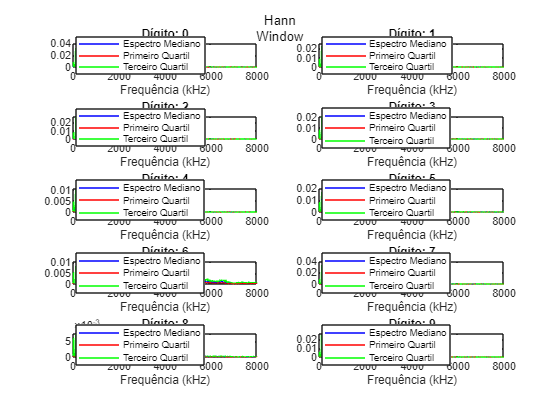


% Hann
num_casos = dadosTotal{1}.dadosFreq / 2;
espectro_mediano = zeros(numFich, num_casos);
primeiro_quartil = zeros(numFich, num_casos);
terceiro_quartil = zeros(numFich, num_casos);

figure;

for i = 1:numFich

    all_spectra = zeros(50, num_casos);
    
    for j = 1:50
        % Obter o áudio e a frequência de amostragem do arquivo atual
        audio = dadosTotal{(i - 1) * 50 + j}.amplitude;
        fs = dadosTotal{(i - 1) * 50 + j}.dadosFreq;

        sinal = [audio; zeros(48000 - length(audio), 1)];
        window = hann(48000);
        sinal = sinal .* window;

        % Calculo do espectro de amplitude
        S = fft(sinal, num_casos); %transformada de fourier
        all_spectra(j, :) = abs(S) / num_casos;
    end

    % Calcula o espectro de amplitude mediano para cada dígito
    espectro_mediano(i, :) = median(all_spectra, 1);
    
    % Calcula o primeiro quartil para cada dígito
    primeiro_quartil(i, :) = quantile(all_spectra, 0.25);
    
    % Calcula o terceiro quartil para cada dígito
    terceiro_quartil(i, :) = quantile(all_spectra, 0.75);
    
    freq = ((0:num_casos - 1) * (fs / num_casos));

    subplot(numFich / 2, 2, i)

    plot(freq, espectro_mediano(i,:), 'Color', 'b');

    hold on

    plot(freq, primeiro_quartil(i,:), 'Color', 'r');

    hold on

    plot(freq, terceiro_quartil(i,:), 'Color', 'g');
    
    hold off

    xlim([0, 8000]);
    xlabel('Frequência (kHz)');
    title(['Dígito: ' num2str(i - 1)]);
    legend('Espectro Mediano', 'Primeiro Quartil', 'Terceiro Quartil', 'Location', 'best');
end
annotation('textbox', [0.5, 0.98, 0, 0],'String', 'Hann Window','EdgeColor', 'none','HorizontalAlignment', 'center');

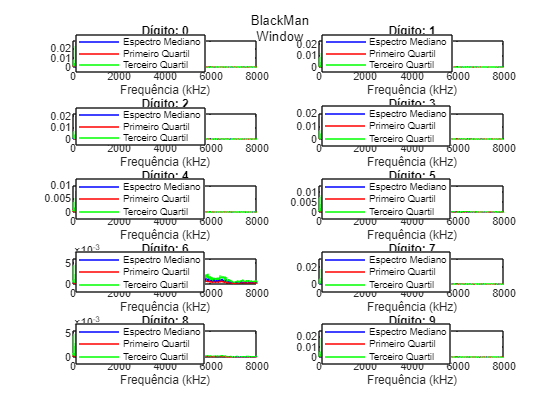


% BlackMan
num_casos = dadosTotal{1}.dadosFreq / 2;
espectro_mediano = zeros(numFich, num_casos);
primeiro_quartil = zeros(numFich, num_casos);
terceiro_quartil = zeros(numFich, num_casos);

figure;

for i = 1:numFich

    all_spectra = zeros(50, num_casos);
    
    for j = 1:50
        % Obter o áudio e a frequência de amostragem do arquivo atual
        audio = dadosTotal{(i - 1) * 50 + j}.amplitude;
        fs = dadosTotal{(i - 1) * 50 + j}.dadosFreq;

        sinal = [audio; zeros(48000 - length(audio), 1)];
        window = blackman(48000);
        sinal = sinal .* window;

        % Calculo do espectro de amplitude
        S = fft(sinal, num_casos); %transformada de fourier
        all_spectra(j, :) = abs(S) / num_casos;

    end

    % Calcula o espectro de amplitude mediano para cada dígito
    espectro_mediano(i, :) = median(all_spectra, 1);
    
    % Calcula o primeiro quartil para cada dígito
    primeiro_quartil(i, :) = quantile(all_spectra, 0.25);
    
    % Calcula o terceiro quartil para cada dígito
    terceiro_quartil(i, :) = quantile(all_spectra, 0.75);
    
    freq = ((0:num_casos - 1) * (fs / num_casos));

    subplot(numFich / 2, 2, i)

    plot(freq, espectro_mediano(i,:), 'Color', 'b');

    hold on

    plot(freq, primeiro_quartil(i,:), 'Color', 'r');

    hold on

    plot(freq, terceiro_quartil(i,:), 'Color', 'g');
    
    hold off

    xlim([0, 8000]);
    xlabel('Frequência (kHz)');
    title(['Dígito: ' num2str(i - 1)]);
    legend('Espectro Mediano', 'Primeiro Quartil', 'Terceiro Quartil', 'Location', 'best');
end
annotation('textbox', [0.5, 0.98, 0, 0],'String', 'BlackMan Window','EdgeColor', 'none','HorizontalAlignment', 'center');

A janela de Hamming tem uma resposta de frequência mais suave em comparação com uma janela retangular, o que ajuda a reduzir perdas espectrais, mas possui lóbulos laterais mais altos em comparação com a janela de Hann.

A janela de Hann tem uma resposta de frequência mais estreita e menos perdas espectrais em comparação com a janela de Hamming, mas possui uma atenuação mais lenta nas extremidades.

A janela de Blackman possui um lobo principal mais estreito e lóbulos laterais mais baixos em comparação com as janelas de Hamming e Hann. Isto resulta em uma melhor supressão de perdas espectrais, mas com uma atenuação mais lenta nas extremidades.


% Cálculo das caracteristicas
max_posicoes = zeros(1,10 * 50);
max_amplitudes = zeros(1,10 * 50);
media_espectral = zeros(1,10 * 50);

idx = 1;
for i = 1:10
    for j = 1:50
        [ma, mp] = max(dadosTotal{(i - 1) * 50 + j}.energia);
        max_posicoes(idx) = mp;
        max_amplitudes(idx) = ma;
        media_espectral(idx) = mean(dadosTotal{(i - 1) * 50 + j}.energia);
        
        idx = idx + 1;
    end
end

% Grafico 3D
figure;
scatter3(max_posicoes, max_amplitudes, media_espectral, 50, (0:numFichTotal - 1), 'filled');
xlabel('Max Posicoes');
ylabel('Max Amplitudes');
zlabel('Media Espectral');
title('Relação entre Max Posicoes, Max Amplitudes e Media Espectral');
colorbar;
colormap(parula(numFichTotal));

Para as nossas características escolhemos a Posição do máximo (Max Posições), a amplitude desse máximo (Max Amplitudes) e média do espetro.

Uma das vantagens de escolha destas é que são fáceis de interpretar pois estão relacionadas. Ao comparar os mesmos dígitos é expectável que a sua amplitude máxima seja semelhante e que se encontre no mesmo sitio. Podemos fazer esta comparação entre digitos diferentes e perceber onde é que estes variam. Por exemplo, o numero 6 tende a ter um pico no inicio enquanto que o numero 3 tende a ter um pico no meio.

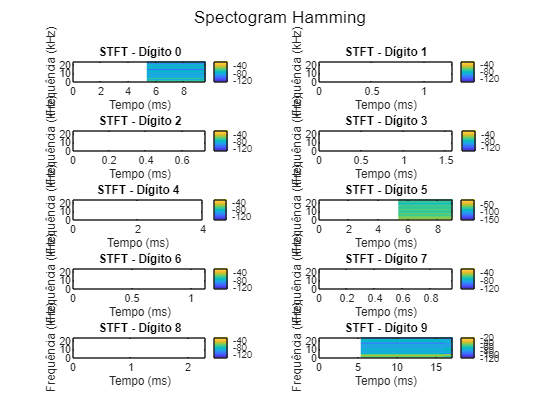


% Meta 3
% Calculo da STFT para cada digito
window_size = 1024;
nfft = window_size;
noverlap = 0.25;

window = hamming(window_size);

figure;

for i = 1:numFich
    audio = dados{i}.amplitude; 
    
    [S, freq, time] = spectrogram(audio, window, round(overlap*window_size), nfft, dados{i}.dadosFreq);

    % Calcular o espectro de amplitude para frequências positivas
    A_hamming = abs(S(1:window_size/2+1,:));

    % Normalizar o espectro de amplitude pelo número de amostras
    A_hamming = A_hamming/window_size;
    
    subplot(numFich / 2, 2, i);
    imagesc(time * 1000, freq / 1000, 20*log10(abs(A_hamming)));
    axis xy;
    xlabel('Tempo (ms)');
    ylabel('Frequência (kHz)');
    title(['STFT - Dígito ' num2str(i-1)]);
    colorbar;
sgtitle('Spectogram Hamming');
end


window = hann(window_size);

figure;

for i = 1:numFich
    audio = dados{i}.amplitude; 
    
    [S, freq, time] = spectrogram(audio, window, round(overlap*window_size), nfft, dados{i}.dadosFreq);

    % Calcular o espectro de amplitude para frequências positivas
    A_hann = abs(S(1:window_size/2+1,:));

    % Normalizar o espectro de amplitude pelo número de amostras
    A_hann = A_hann/window_size;
    
    subplot(numFich / 2, 2, i);
    imagesc(time * 1000, freq / 1000, 20*log10(abs(A_hann)));
    axis xy;
    xlabel('Tempo (ms)');
    ylabel('Frequência (kHz)');
    title(['STFT - Dígito ' num2str(i-1)]);
    colorbar;
sgtitle('Spectogram Hann');
end

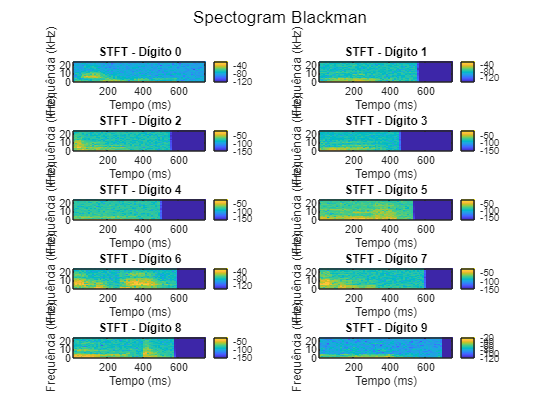


window = blackman(window_size);

figure;

for i = 1:numFich
    audio = dados{i}.amplitude; 
    
    [S, freq, time] = spectrogram(audio, window, round(overlap*window_size), nfft, dados{i}.dadosFreq);

    % Calcular o espectro de amplitude para frequências positivas
    A_blackman = abs(S(1:window_size/2+1,:));

    % Normalizar o espectro de amplitude pelo número de amostras
    A_blackman = A_blackman/window_size;
    
    subplot(numFich / 2, 2, i);
    imagesc(time * 1000, freq / 1000, 20*log10(abs(A_blackman)));
    axis xy;
    xlabel('Tempo (ms)');
    ylabel('Frequência (kHz)');
    title(['STFT - Dígito ' num2str(i-1)]);
    colorbar;
sgtitle('Spectogram Blackman');
end